# PHY 329 Homework 1

## Ryan Schlimme (eid: rjs4499)

# Problem 5.7

## Part a)

format longg
xRange = -2: 0.01 : 6;       % define x range
fx = @(x) -12 - 21*x + 18*x.^2 -2.75*x.^3;      % input polynomial

grid on;
figure(1); plot(xRange, fx(xRange));          % graph polynomial over range
hold on;
yline(0);
hold off

The graph seems to cross y = 0 three times, as we would expect from a third-order polynomial. If we zoom in iteratively on the three roots, we can provide an estimate of the roots.

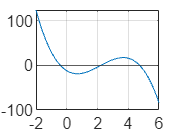

xRange = -2: 0.01 : 6;       % define x range
fx = @(x) -12 - 21*x + 18*x.^2 -2.75*x.^3;      % input polynomial

grid on;

figure(2); plot(xRange, fx(xRange));          % graph polynomial over range
hold on;
xlim([-0.4191 -0.4107])
ylim([-0.113 0.149])
yline(0);
hold off

fx(-0.414675)

ans =      -0.000538234242057928


From visual inspection, there appears to be a root around x = -0.414675. If we plug this into our polynomial, we should expect to yield a result close to 0.

Our visual guess took several iterations of zooming in but yields a respectible guess.

Continuing this method, we can check for the other two roots.

xRange = -2: 0.01 : 6;       % define x range
fx = @(x) -12 - 21*x + 18*x.^2 -2.75*x.^3;      % input polynomial

grid on;
figure(3); plot(xRange, fx(xRange));          % graph polynomial over range
hold on;
yline(0);
xlim([2.21825 2.22119])
ylim([-0.045 0.047])
hold off



fx(2.2198)

ans =      -0.000334152577998736


Second root around x = 2.2198.

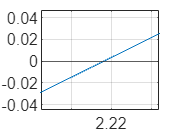

xRange = -2: 0.01 : 6;       % define x range
fx = @(x) -12 - 21*x + 18*x.^2 -2.75*x.^3;      % input polynomial

grid on;

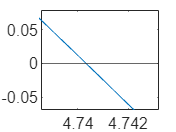



figure(4); plot(xRange, fx(xRange));          % graph polynomial over range
hold on;
yline(0);
xlim([4.73852 4.74324])
ylim([-0.069 0.079])
hold off


fx(4.740325)

ans =       2.35181900052339e-05


Third root around x = 4.740325.

## Part b)

fx = @(x) -12 - 21*x + 18*x.^2 -2.75*x.^3;
xl = -1;
xu = 0;
es = 0.01;
[root, eval] = bisect(fx, xl, xu, es)

root =         -0.414703369140625


eval =       0.000521283354707691


Using bisection, our first root is x = -0.4147.

## Part c)

% xi+1 = xi - (f(xu)(xl - xu))/(f(xl)-f(xu))

% We use xl = -1, xu = 0, stopping criteria 1%

fx = @(x) -12 - 21*x + 18*x.^2 -2.75*x.^3;
xl = -1;
xu = 0;
es = 0.01;
xinitial = 0;

[rootregula, error] = regula(fx, xl, xu, es)

rootregula =         -0.414689411620145


error =      0


Using false position, our first root is x = -0.4147 with an error too small to display.

# Problem 5.8

We must determine the first nontrivial solution to sin(x) = x^2. If we rearrange this equation into 0 = x^2 - sin(x), we can solve by rootfinding.

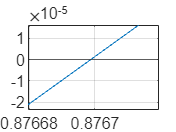

f = @(x) x.^2 - sin(x);
error = 0.02;

xRange = 0.5: 0.01 : 1;
figure(5); plot(xRange, f(xRange));
grid on;
hold on;
yline(0);
xlim([0.8766796 0.8767195])
ylim([-0.0000237 0.0000162])
hold off


f(0.876695)

ans =      -3.47657797906686e-05


Graphically, after zooming in heavily, we observe a root of xr = 0.876695 which quite accurately produces f(xr) = 0.

xl = 0.5;
xu = 1;
es = 0.02;
[root, eval] = bisect(f, xl, xu, es)

root =            0.8768310546875


eval =       0.000116783277113508


Using bisection, we achieve a root of 0.8768 rad with error 0.0001.

# Problem 5.9

We must determine the positive real root of ln(x^2) = 0.7

## Part a)

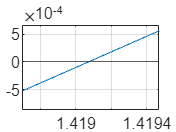

f = @(x) log(x.^2) - 0.7;
xRange = 1: 0.01 : 1.5;
figure(6); plot(xRange, f(xRange));
grid on;
hold on;
yline(0);
xlim([1.418703 1.419469])
ylim([-0.00087 0.00067])
hold off


f(1.4197)

ans =       0.000891163374782344


Graphically, it appears there is a root at 1.4197.

## Part b)

xl = 0.5;
xu = 2;
maxit = 3;
[root, eval] = bisect(f, xl, xu, maxit)

root =                  1.4140625


eval =       -0.00706646530758281


Using three iterations of bisection, we achieve a root of 1.4140625.

## Part c)

xl = 0.5;
xu = 2;

xnext = xu - (f(xu)*(xl-xu))/(f(xl)-f(xu))

xnext =           1.62870744823335


f(xnext)

ans =          0.275573447405012


f(xu)

ans =          0.686294361119891


xu = xnext

xu =           1.62870744823335



xnext = xu - (f(xu)*(xl-xu))/(f(xl)-f(xu))

xnext =           1.49701430202987


f(xnext)

ans =          0.106945318372039


f(xu)

ans =          0.275573447405012


xu = xnext

xu =           1.49701430202987



xnext = xu - (f(xu)*(xl-xu))/(f(xl)-f(xu))

xnext =            1.4483985429092


With three iterations of Regula-Falsi, we arrive at a root of x = 1.448. Evidently, Regula-Falsi requires more iterations for this type of function.

# Problem 5.19

f = @(x) (x.^2 + 0.85.^2).^(3/2)*1.25*4*pi*epsilon/q/Q - x;
F = 1.25;
epsilon = 8.9e-12;
q = 2e-5;
Q = q;


fzero(f, 0.2)

Error using fzero>localFirstFcnEval
FZERO cannot continue because user-supplied function_handle ==> @(x)(x.^2+0.85.^2).^(3/2)*1.25*4*pi*epsilon/q/Q-x
failed with the error below.

 Unrecognized function or variable 'epsilon'.

Error in fzero (line 305)
    fx = localFirstFcnEval(FunFcn,FunFcnIn,x,varargin{:});

fzero(f, 1)

The distances which solve the equation given the parameters are x = 0.2410 m and x = 1.2913 m.

# Problem 5.15

Using bisection, solve for when the derivative is 0. Then, substitute into the original equation to determine the value of max deflection given the parameters.

deriv = @(x) 2.5/(120*50000*I*L)*(-5*x.^4+6*L.^2*x.^2-L.^4);
f = @(x) 2.5/(120*50000*I*L)*(-x.^5+2*L.^2*x.^3-L.^4*x);

L = 600;
E = 50000;
I = 30000;
w = 2.5;

root = fzero(deriv, 270)
fzero(deriv, 600)

f(root)

The two places where the derivative is 0 are x = 268.32816 cm and x = 600 cm. The latter of the two is nonphysical sense that is the end of the beam. Plugging this root into the original formula, we get a maximum deflection of -0.5152 cm.

Since this fourth order polynomial does not cross the y-axis (it merely touches it at four points), we cannot use bisection.

# Problem 5.24

Use bisection to determine the height, h, of the portion of the figure above the water, along with archimede's principle that the buoyancy force is equal to the weight of fluid displaced by submerged portion. 

To find h above the water, we must find the point where the weight of the displaced water equals the weight of the object.

r = 1;
water_density = 1000;
sphere_density = 200;

sphereF = 4/3*pi*r^3*sphere_density*9.81

sphereF = 8.2184e+03


waterF = @(h) water_density*9.81* (4/3*pi*r^3 - (pi*h^2 * (3*r - h)/3)) - sphereF;

root = bisect(waterF, 1, 1.5)

root = 1.4257

By equating the mass of water displaced to the mass of the ball, we find the height of the section above water to be 1.4257 m.

# Problem 6.3

Determine the highest real root

## Part a) Graphically

f = @(x) x.^3 - 6*x.^2 + 11*x - 6.1;
xRange = 2: 0.01 : 4;
figure(7); plot(xRange, f(xRange));
grid on;
hold on;
yline(0);
xlim([3.046585 3.046717])
ylim([-0.000108 0.000353])
hold off

f(3.04665)

Graphically, the highest root is approximately at x = 3.04665.

## Part b) Newton-Raphson

df = @(x) 3*x.^2 - 12*x + 11;
maxit = 3;
x0 = 3.5;

root = newtraph(f, df, x0, maxit)

Using three iterations of Newton-Raphson with initial guess x = 3.5, we produce a root of 3.0473.

## Part c) Secant

maxit = 3;
x0 = 2.5;
x1 = 3.5;

root = secant(f, x0, x1, maxit)

Using three iterations of Secant with initial guesses x0 = 2.5 and x1 = 3.5, we arrive at a root of x = 3.038.

## Part d) Modified Secant

maxit = 3;
x0 = 3.5;
delta = 0.01;

root = modsecant(f, x0, delta, maxit)

Using three iterations of the Modified Secant with initial guess x0 = 3.5 and delta = 0.01, we arrive at root x = 3.049.

## Part e) All Roots

p = [1 -6 11 -6.1];
roots = roots(p)

Using the built-in roots function for polynomials, MATLAB produced roots of x = 3.047, 1.899, 1.054.

# Problem 6.4

Determine the lowest positive root

## Part a) Graphically

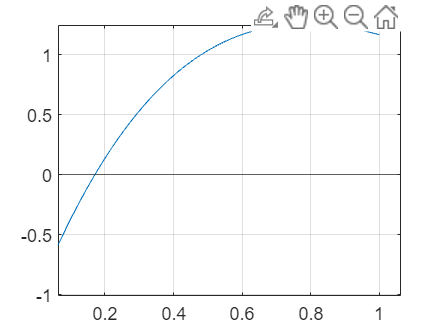

f = @(x) 7.*sin(x).*exp(-1*x)-1;

xRange = 0: 0.01 : 1;
figure(8); plot(xRange, f(xRange));
grid on;
hold on;
yline(0);
xlim([0.170067 0.170401])
ylim([-0.00035 0.00049])
hold off


f(0.17018)

ans = 3.0102e-08

Graphically, we can estimate a root of x = 0.17018

## Part b) Wegstein

x0 = -0.5;
x1 = 0.5;

root = wegstein(f, x0, x1)

root = 0.2182

Using Wegstein, we get a result of x = 0.2182.

## Part c) Newton-Raphson

df = @(x) 7.*exp(-1*x)*(cos(x)-sin(x));
maxit = 3;
x0 = 0.3;

root = newtraph(f, df, x0, maxit)

root = 0.1702

Using Newton-Raphson, we get a result of 0.1702.

## Part d) Modified Secant

maxit = 5;
x0 = 0.3;
delta = 0.01;

root = modsecant(f, x0, delta, maxit)

root = 0.1702

Using modified secant, we produce a result of x = 0.1702.

# Problem 6.19

Z = @(w) ((1/225^2)+(w*C-1/(w*L))^2)^(-1/2) - 100;
C = 0.6e-6;
L = 0.5;

root = fzero(Z, 200)

Given the parameters, we can achieve an impedance of 100 Ohms at an angular frequency of 220.020 rad/s.

# Problem 6.20

f = @(d) (2*k*d.^(5/2))/5 + 0.5*K*d.^2-m*g*d-m*g*h;
K = 40000;
k = 40;
m = 95;
g = 9.81;
h = 0.43;

root = fzero(f, 0.2)

Given the parameters, we find d = 0.1667 m.

# Problem 6.21

f = @(z) tan(z)*90-(9.81/(2*v0^2*cos(z)^2))*90^2+y0-y;
x = 90;
g = 9.81;
v0 = 30;
y0 = 1.8;
y = 1;

root = fzero(f, 0.6)

root = 0.6625

fzero(f, 0.9)

ans = 0.8994

MATLAB has found solution theta = 0.663 rad. If graphed, we see there are infinitely many solutions, as expected from a trigonometric function. However, there also appears to be a solution around theta = 0.9. While not physical, this could be a consequence of the cosine square function.

# Problem 6.38

W = 9000;
L = 45;
Ac = 6.362e-4;
E = 1.5e11;

alpha = L / (Ac * E);

f = @(F) 2*F*alpha*L + (alpha*F)^2 - ((4500/F)*(alpha*F+L))^2;

root = fzero(f, 100000)

root = 9.8913e+04


d = 4500/root * (root*alpha + L)

d = 2.0494

elong = root * alpha

elong = 0.0466

By treating the problem as a root find, we find a solution for F = 98,913 N. We can then find the deflection d = 2.0494 m and the elongation L' - L = 0.0466 m. Therefore, each cable elongated 0.0466 m due to the weight, resulting in a vertical deflection downward 2.0494 m.

# Define Our Functions

% bisect function

function [root, fx, ea, iter] = bisect(func, xl, xu, es, maxit, varargin)
if nargin<3, error('at least 3 input args required'), end
test = func(xl, varargin{:})*func(xu, varargin{:});
if test>0, error('no sign change'), end
if nargin<4 || isempty(es), es = 0.0001; end
if nargin<5 || isempty(maxit), maxit = 50; end
iter = 0; xr = xl; ea = 100;
while (1)
    xrold = xr; xr = (xl + xu)/2;
    iter = iter + 1;
    if xr ~= 0, ea = abs((xr - xrold)/xr)*100; end
    test = func(xl, varargin{:})*func(xr, varargin{:});
    if test <0
        xu = xr;
    elseif test > 0
        xl = xr;
    else
        ea = 0;
    end
    if ea <= es || iter >= maxit, break, end
end
root = xr; fx = func(xr, varargin{:});
end


% regula falsi
function [root, err] = regula(f, x0, x1, epsilon)
err=abs(x1-x0);
 %Formula: x2=x1-((x1-x0)/(f(x1)-f(x0)))*f(x1);
 if f(x0)*f(x1)>0 
    disp('Enter valid interval !!!');
    return
 else
%fprintf('\n x0 \t \t  x1 \t \t x2 \t \t f(x0) \t\t f(x1) \t\t  f(x2)');     
    while err > epsilon
        x2=x1-((x1-x0)/(f(x1)-f(x0)))*f(x1);
        root=x2;
    %fprintf('\n %0.4f \t %0.4f \t %0.5f \t %0.4f \t %0.4f\t %0.4f',x0,x1,x2,f(x0),f(x1),f(x2));
        if f(x1)*f(x2)<0
            x1=x2;
        else
            x0=x2;
        end
       err=abs(x0-x1);
    end
 end
end


% Newton-Raphson
function [root, ea, iter] = newtraph(func, dfunc, xr, es, maxit, varargin)
% func: function, dfunc: derivative, xr: initial guess, es: error, maxit:
% maximum iterations
if nargin<3, error('at least 3 input args requires'), end
if nargin<4 || isempty(es), es = 0.0001; end
if nargin<5 || isempty(maxit), maxit = 50; end
iter = 0;
while(1)
    xrold = xr;
    xr = xr - func(xr)/dfunc(xr);
    iter = iter + 1;
    if xr ~= 0, ea = abs((xr-xrold)/xr)*100; end
    if ea <= es || iter >= maxit, break, end
end
root = xr;
end


% Secant
function [root, ea, iter] = secant(func, x0, x1, es, maxit, varargin)
% func: function, x0: left guess, x1: right guess, es: error, maxit:
% maximum iterations
if nargin<3, error('at least 3 input args requires'), end
if nargin<4 || isempty(es), es = 0.0001; end
if nargin<5 || isempty(maxit), maxit = 50; end
iter = 0;
while(1)
    x2 = x1 - (func(x1)*(x0-x1))/(func(x0)-func(x1));
    iter = iter + 1;
    if x2 ~= 0, ea = abs((x2-x1)/x2)*100; end
    if ea <= es || iter >= maxit, break, end
    x0 = x1;
    x1 = x2;
end
root = x2;
end


% Modified Secant
function [root, ea, iter] = modsecant(func, x0, delta, es, maxit, varargin)
% Inputs:
%   func = function
%   x0 = initial guess
%   delta = step variable
%   es = error
%   maxit = maximum iterations
% Outputs:
%   root = root
%   ea = error
%   iter = number of iterations
if nargin<3, error('at least 3 input args requires'), end
if nargin<4 || isempty(es), es = 0.0001; end
if nargin<5 || isempty(maxit), maxit = 50; end
iter = 0;
while(1)
    x1 = x0 - (delta*x0*func(x0))/(func(x0+delta*x0)-func(x0));
    iter = iter + 1;
    if x1 ~= 0, ea = abs((x1-x0)/x1)*100; end
    if ea <= es || iter >= maxit, break, end
    x0 = x1;
end
root = x1;
end


% Wegstein
function [x2, fx2, ea, iter] = wegstein(g, x0, x1, es, maxit)
% Inputs:
%   g = input function g(x)
%   x0, x1 = initial guesses for x
%   es = relative error stopping criterion
%   maxit = maximum iterations
% Outputs:
%   x2 = root
%   fx2 = function value at root
%   ea = relative error
%   iter = number of iterations
if nargin<3, error('at least 3 args required'), end
if nargin<4 || isempty(es), es = 0.0001; end
if nargin<5 || isempty(maxit), maxit = 50; end

iter = 0; ea = 1;
while(1)
    x2 = (x1*g(x0)-x0*g(x1))/(x1-x0-g(x1)+g(x0));
    iter = iter + 1;
    if x2 ~= 0, ea = abs((x2-x1)/x2); end
    if (ea<=es || iter>=maxit), break, end
    x0 = x1; x1 = x2;
end
fx2 = g(x2);
end